# **R-factor: Visualize geomechanical changes as a movie**

## Introduction

Several models were generated with COMSOL

- Model 5 - Homogeneous model

- Model 6 - Groningen model, different permeability on top and bottom of the reservoir

- Model 7 - Groningen model, the same permeability on top and bottom of the reservoir

This script visualize changes due to fluid production for Model 5

**Authors**: Ivan Abakumov

**Publication date**: 28th of October 2019

**E-mail**: ivan.abakumov@fu-berlin.de

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Load G-file and comsol data

Results = MLD('/home/ivan/Desktop/Comsol/My_model_7_results.mat');
G = MLD('/home/ivan/Desktop/Comsol/My_model_7_G_file.mat');

%loops = 101;
%F(loops) = struct('cdata',[],'colormap',[]);


%for tt = 1:1:loops 
tt = 1

tt = 1

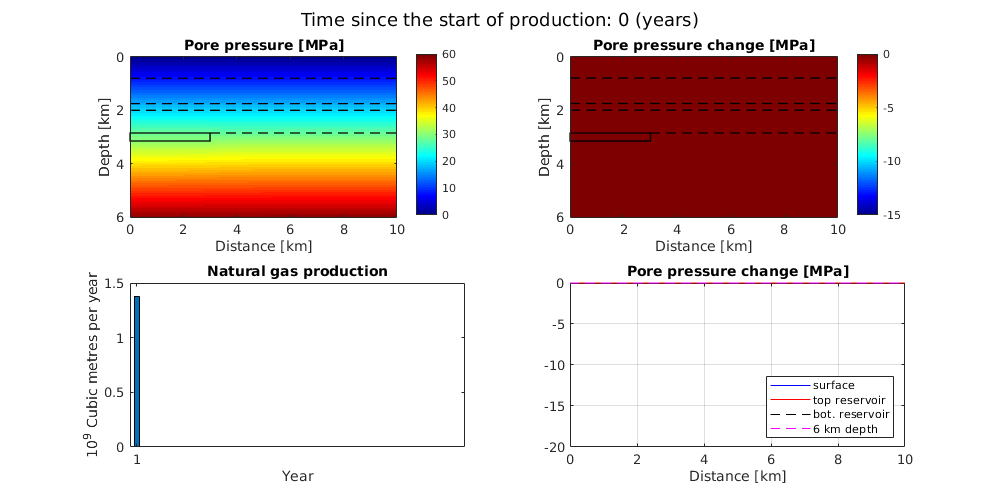


    figure(223)
    fig = figure('Position', [1 1 1000 500]);
    
    
    subplot(2,2,1)
    imagesc(G.xx/1e3, G.zz/1e3, Results.pressure(:,:,tt)'/1e6)
    hold on 
    rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
    colormap jet
    colorbar
    axis('equal')
    axis([0 10 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Pore pressure [MPa]')
    caxis([0 60])

    
    subplot(2,2,2)
    imagesc(G.xx/1e3, G.zz/1e3, (Results.pressure(:,:,tt)'-Results.pressure(:,:,1)')/1e6)
    hold on 
    rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
    colormap jet
    colorbar
    axis('equal')
    axis([0 10 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Pore pressure change [MPa]')
    caxis([-15 0])
    
    
    subplot(2,2,3)
    % 92% of natural gas is methane
    % methanes density is 0.717 kg/m³ (in normac conditions T = 0 C, p = 1 atm)
    
    Density = 0.717; 
    Production_rate = 31.4; % kg/s
    Production_per_year = Production_rate*60*60*24*365;
    Volume_per_year = Production_per_year/Density;
    years = 1:round(tt/2);
    production = Volume_per_year*ones(size(years));
    bar(years, production/1e9)
    axis([0 50 0 1.5])   
    ticks()
    title('Natural gas production')
    xlabel('Year')
    ylabel('10^9 Cubic metres per year')
    
    
    subplot(2,2,4)
    plot(G.xx/1e3, (Results.pressure(:,1,tt)'-Results.pressure(:,1,1)')/1e6, 'b')
    hold on
    plot(G.xx/1e3, (Results.pressure(:,286,tt)'-Results.pressure(:,286,1)')/1e6, 'r')
    plot(G.xx/1e3, (Results.pressure(:,316,tt)'-Results.pressure(:,316,1)')/1e6, 'k--')
    plot(G.xx/1e3, (Results.pressure(:,601,tt)'-Results.pressure(:,601,1)')/1e6, 'm--')
    xlabel('Distance [km]')
    grid on
    title('Pore pressure change [MPa]')
    legend('surface','top reservoir','bot. reservoir', '6 km depth', 'Location', 'southeast')
    axis([0 10 -20 0])
    
    
    sgtitle(['Time since the start of production: ' num2str(G.tt(tt),2) ' (years)'] )



%    F(tt) = getframe(gcf);
%    pause(0.03);
%    disp(tt)
%end

## Save Movie

%v = VideoWriter('/home/ivan/Desktop/test3','Motion JPEG AVI');
%v.FrameRate = 5;
%v.Quality = 100;
%open(v);
%writeVideo(v,F);
%close(v);